# PSP ASA PSPSP 2025 PS2

## Hohmann Transfer Practice

You should get a plot that looks the same as the one in the start of the question, however, while plotting code is provided, we heavily suggest drawing diagrams for each problem so that you can make sure your answers make sense.

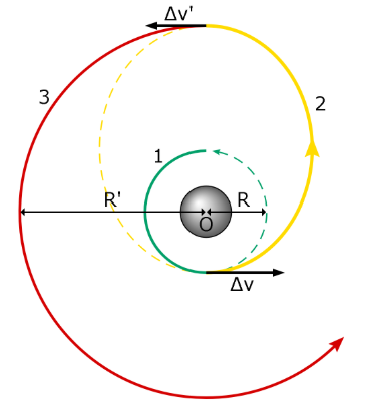

### Physical Constants (from *Table of Constants*)

R_E = 6378.1363; % [km] Earth radius
mu_E = 398600.4415; % [km3 / s2] Earth gravitational parameter

R_mn = 1738.2; % [km] Moon radius
mu_mn = 4902.8005821478; % [km3 / s2] Moon gravitational parameter

% Add helper function folder to path (for plotting)
addpath('Helper Functions')  

### Problem 1 - Geostationary Satellite Inspection at the ISS

Alice is on a mission to retrieve a satellite from geostationary orbit and bring it to the ISS for detailed inspection. The rocket launch is scheduled so that a Hohmann transfer will make Alice rendezvous with the satellite. However, NASA forgot to think about how she will get to the ISS so they have asked you to plan the ISS redezvous.

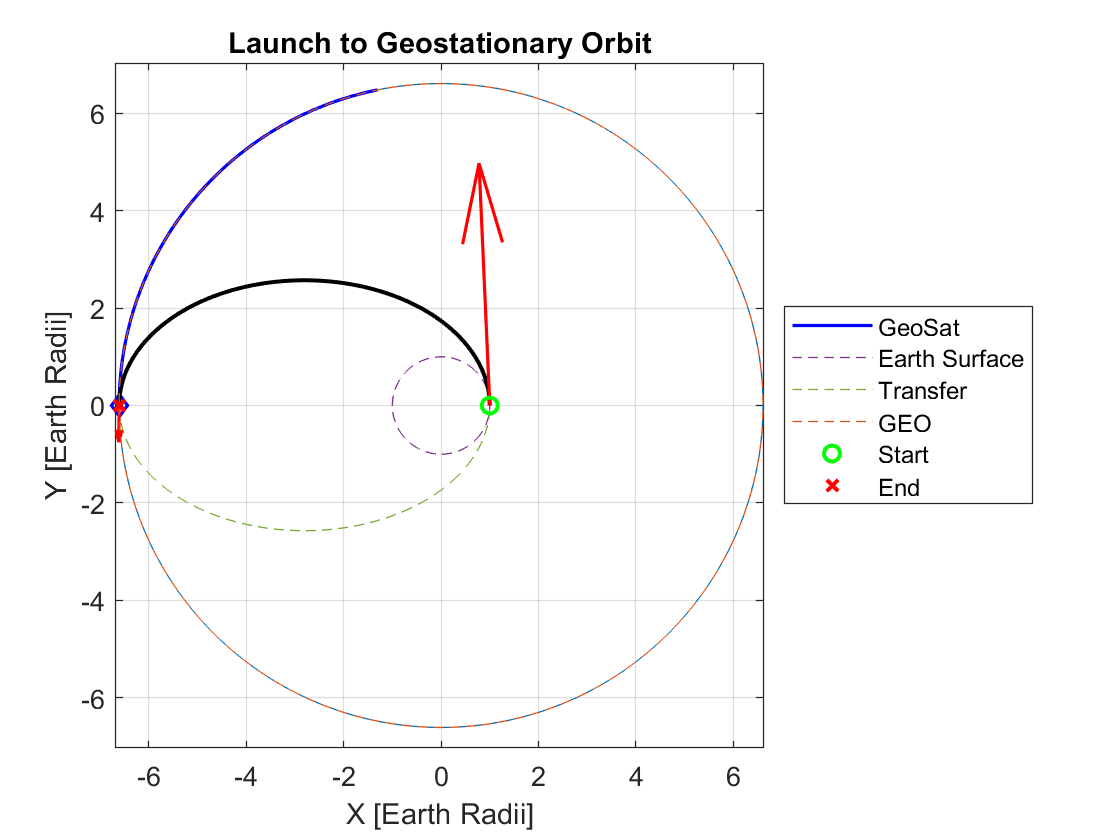

### Problem 1.1 - Launch to Geostationary Orbit

Starting from the Earth's surface, design a trajectory to get Alice to geostationary orbit using a Hohmann transfer. The true anomaly when you launch is 0 degrees.

#### Given Values

h_geo = 35786; % [km] geostationary altitude
thetastar_0_sc = 0; % [deg] initial true anomaly

#### a) Calculate the semimajor axis, eccentricity, and period of the transfer orbit. Geostationary transfer orbits usually have periods around 10.5 hours, is yours close (within 3 minutes)?


% Values needed for plotting
a_trans_geo = ; % [km] semimajor axis of transfer orbit
e_trans_geo = ; % [] eccentricity of transfer orbit
P_trans_geo = ; % [s] period of transfer orbit

#### b) Calculate the delta V needed for this transfer (make sure to have the correct sign). How much does including the help from the Earth's rotation at launch help? (use the value for Axial Rotation Period in the *Table of Constants*)


% Values needed for plotting
delta_v_geo_1 = ; % [km] delta v for first burn
delta_v_geo_2 = ; % [km] delta v for second burn

#### c) What is the true anomaly of the geostationary satellite at Alice's launch?


% Values needed for plotting
thetastar_geo_0 = ; % [deg] inital true anomaly of the geostationary satellite

#### d) Plot the transfer using the provided plotting code

% Plot
ae_sc = [R_E, a_trans_geo, h_geo + R_E; 
         0, e_trans_geo, 0];
objects_1a = struct();
objects_1a.a = h_geo + R_E;
objects_1a.e = 0;
objects_1a.w = deg2rad(thetastar_geo_0);
objects_1a.c = "b";
objects_1a.t_max = -1;
objects_1a.name = "GeoSat";
delta_v_1a = [delta_v_geo_1, delta_v_geo_2];
plot_Hohmann_transfer(0, ae_sc, ["Earth Surface", "Transfer", "GEO"], [0, P_trans_geo / 2, 0], delta_v_1a, objects_1a, mu_E, 200, "Launch to Geostationary Orbit", R_E, "Earth Radii")

### Problem 1.2 - ISS Redezvous from Geostationary Orbit

The International Space Station has a true anomaly of 60 degrees when Alice launches. Construct a Hohmann transfer so Alice rendezvoused with the ISS.

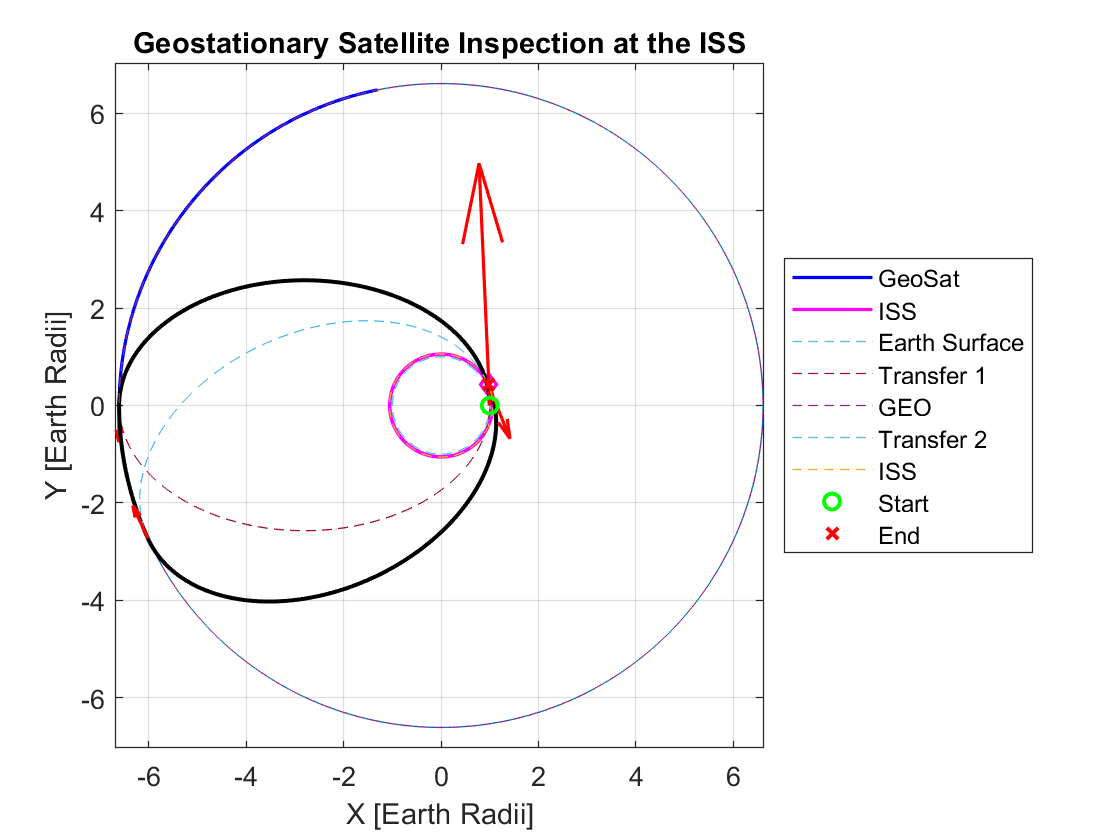

#### Given Values

h_ISS = 378.5; % [km] circular approximation of height ISS orbits at
thetastar_0_ISS = 60; % [deg] 

#### a) What is the true anomaly of the ISS when Alice meets the geostationary satellite?

#### b) Calculate the Hohmann transfer to the ISS. How much delta V is needed?


% Values needed for plotting
a_trans_ISS = ; % [km] semimajor axis of transfer orbit
e_trans_ISS = ; % [] eccentricity of transfer orbit
P_trans_ISS = ; % [s] period of transfer orbit
delta_v_ISS_1 = ; % [km] delta v for first burn
delta_v_ISS_2 = ; % [km] delta v for second burn

#### c) How long must Alice wait before performing the Hohmann transfer so that she successfully rendezvouses with the ISS?


% Values needed for plotting
T_wait = ; % [s] time waited before transfer to ISS after getting into geostationary orbit

#### d) Plot Alice's mission using the provided plotting code

% Plot
ae_sc = [R_E, a_trans_geo, h_geo + R_E, a_trans_ISS, h_ISS + R_E; 
         0, e_trans_geo, 0, e_trans_ISS, 0];
objects_1 = struct();
objects_1.a = [h_geo + R_E, h_ISS + R_E];
objects_1.e = [0, 0];
objects_1.w = [deg2rad(thetastar_geo_0), deg2rad(thetastar_0_ISS)];
objects_1.c = ["b", "m"];
objects_1.t_max = [P_trans_geo / 2, -1];
objects_1.name = ["GeoSat", "ISS"];
delta_v_1 = [delta_v_1a, delta_v_ISS_1, delta_v_ISS_2];
plot_Hohmann_transfer(0, ae_sc, ["Earth Surface", "Transfer 1", "GEO", "Transfer 2", "ISS"], [0, P_trans_geo / 2, T_wait, P_trans_ISS / 2, 0], delta_v_1, objects_1, mu_E, 200, "Geostationary Satellite Inspection at the ISS", R_E, "Earth Radii")

### Problem 2 - Injection into Low Lunar Orbit 

Bob is visiting the Moon for a holiday and is currently in a hyperbolic orbit with an eccentricity of 1.25 and a perilune altitude of 400 km. Create a Hohmann transfer between the hyperbolic flyby trajectory and a circular parking orbit with an altitude of 110 km (Bob's first burn will happen at the perilune of the hyperbolic trajectory).

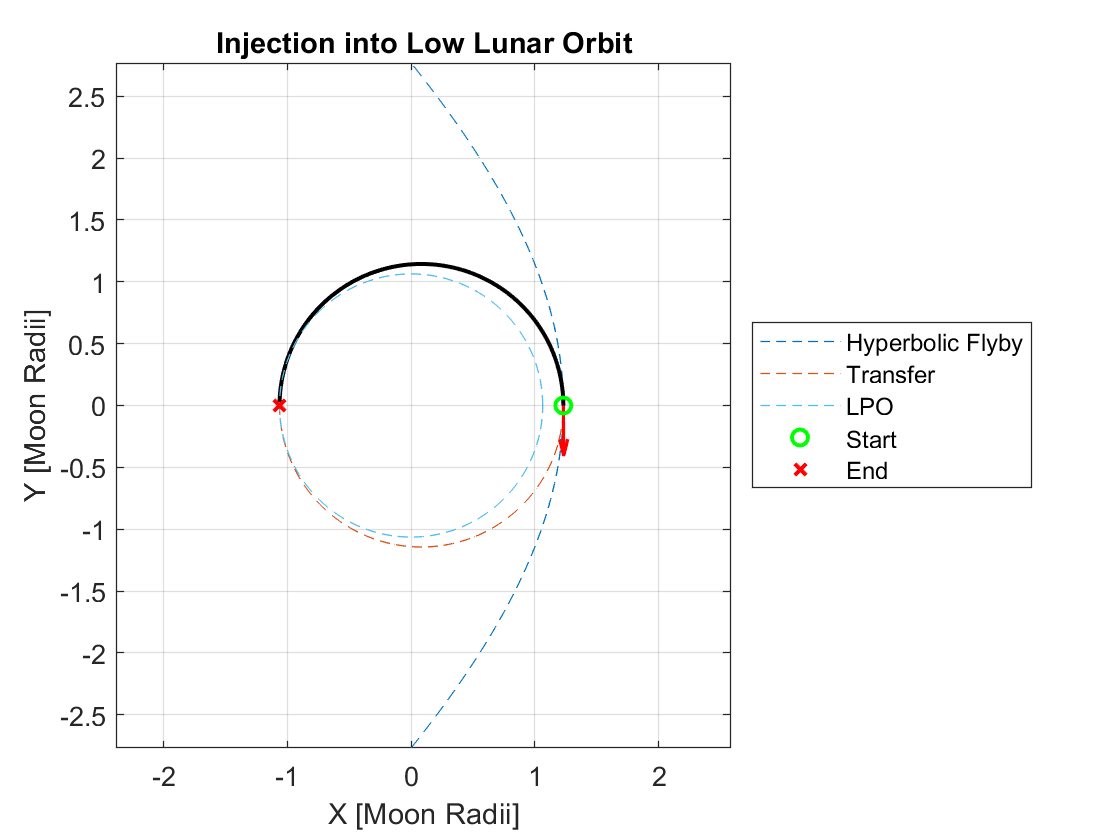

#### Given Values

e_hyp = 1.25; % [] eccentricity of hyperbolic flyby trajectory
h_p_hyp = 400; % [km] perilune of hyperbolic flyby trajectory
h_LPO = 110; % [km] altitude of (planned) lunar parking orbit for Apollo 11 at time of rendezvous

#### a) What is Bob's velocity at the perilune of the hyperbolic flyby trajectory?


% Values needed for plotting
a_hyp = ; % [km] semimajor axis of hyperbolic orbit

#### b) What would the velocity of a circular orbit with the same altitude as the perilune of Bob's flyby trajectory be? A hyperbolic trajectory will always have a velocity greater than $\sqrt{2}$ times the velocity of a circular orbit with the same radius, check your answer with this knowledge.

#### c) Create the Hohmann transfer that gets Bob into the parking orbit. What is the delta V Bob needs?


% Values needed for plotting
a_trans_hyp = ; % [km] semimajor axis of transfer orbit
e_trans_hyp = ; % [] eccentricity of transfer orbit
P_trans_hyp = ; % [s] period of transfer orbit
delta_v_hyp_1 = ; % [km / s] delta v for first burn
delta_v_hyp_2 = ; % [km / s] delta v for second burn

#### d) Plot Bob's transfer using the provided plotting code

% Plot
ae_sc = [a_hyp, a_trans_hyp, h_LPO + R_mn; 
         e_hyp, e_trans_hyp, 0];
objects_2 = struct();
objects_2.a = [];
objects_2.e = [];
objects_2.w = [];
objects_2.c = [];
objects_2.t_max = [];
objects_2.name = [];
delta_v_2 = [delta_v_hyp_1, delta_v_hyp_2];
plot_Hohmann_transfer(0, ae_sc, ["Hyperbolic Flyby", "Transfer", "LPO"], [0, P_trans_hyp / 2, 0], delta_v_2, objects_2, mu_mn, 200, "Injection into Low Lunar Orbit", R_mn, "Moon Radii")